# Exact diagonalization: the Bose–Hubbard model as an example

10.1088/0143-0807/31/3/016

#### Basis Generation

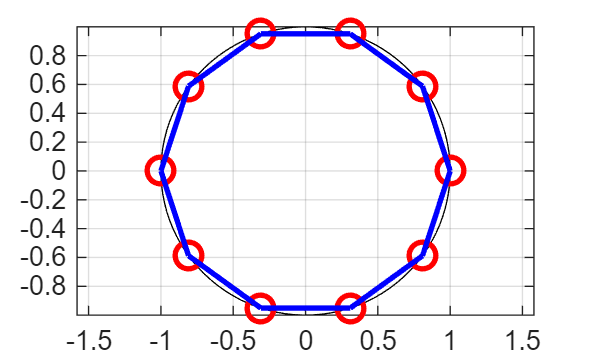


clear;
tic;
% N as atoms number, M as sites number
N_atoms = 10;
N_Sites = 10;
plot_circle_points(N_Sites);

% Dimension is (N+M-1) select N
Dimension = nchoosek(N_atoms + N_Sites - 1, N_atoms);
% Accuracy used to search the Tags
Accuracy = 1e3 * eps;
% Initialize the basis through cell
Basis = repmat({zeros(1, N_Sites)}, Dimension, 1);
% Set the first basis as (N, 0, 0...)
Basis{1}(1) = N_atoms;
% Basis Generation
for ii = 2: Dimension
    Count = find(Basis{ii-1}(1:end-1)~=0, 1, 'last');
    temp = Basis{ii-1};
    if Count <= N_Sites - 1
        if temp(Count) ~= 0 && ~any(temp(Count+1:end-1))
            Basis{ii}(1:Count-1) = Basis{ii-1}(1:Count-1);
            Basis{ii}(Count) = Basis{ii-1}(Count) - 1;
            Basis{ii}(Count + 1) = N_atoms - sum(Basis{ii}(1:Count));
        end
    end
end
Basis = cell2mat(Basis);
toc;

历时 2.215865 秒。


Tag functions, define $|v\rangle =\left(A_{v\;1} ,A_{v\;2} ,\ldotp \ldotp \ldotp ,A_{v\;m} \right)$ as the $v$ th row of Basis


$$T\left(v\right)=\sum_{i=1}^M \sqrt{p_i }A_{v\;i}$$


where $p_i$ is the $i$th prime number

Tags = Basis * Tag_function(N_Sites)';

% Sort the Tag function
[Tags, ind] = sort(Tags);

Setting up the Hamiltonian matrix


$$H=-t\sum_{\langle ij\rangle}(a_i^\dagger a_j + a_j^\dagger a_i)+\frac{U}{2}\sum_{i=1}^M \hat{n_i}(\hat{n}_i -1)$$


% Interacting matrix
H_interaction = spdiags(sum(Basis .* (Basis - (Basis>0)),2), 0, Dimension, Dimension);

% hopping matrix
col = zeros(1, (2*N_Sites+1) * Dimension);
row = zeros(1, (2*N_Sites+1) * Dimension);
val = zeros(1, (2*N_Sites+1) * Dimension);
Count = 1;

% col = [];
% row = [];
% val = [];

% parfor ii = 1: Dimension
for ii = 1: Dimension
    ind_nonzero = find(Basis(ii,:));
    for jj = 1: length(ind_nonzero)
        temp = Basis(ii,:);
        temp(ind_nonzero(jj)) = temp(ind_nonzero(jj)) - 1;
        %% Nearest hopping
        % Left hopping matrix element
        temp_site = ind_nonzero(jj) - 1;
        if temp_site == 0
            temp_site = N_Sites;
        end
        temp(temp_site) = temp(temp_site) + 1;
        temp_Tag = temp * Tag_function(N_Sites)';
        col(Count) = ii;
        row(Count) = ind(abs(Tags - temp_Tag) < Accuracy);
        val(Count) = sqrt(Basis(ii,ind_nonzero(jj)) * (Basis(ii, temp_site)+1));
        %% parfor part 
        % col = [col, ii];
        % row = [row, ind(abs(Tags - temp_Tag) < Accuracy)];
        % val = [val, -t * sqrt(Basis(ii,ind_nonzero(jj)) * (Basis(ii, temp_site)+1))];
        Count = Count + 1;

        % Right hopping matrix element
        temp = Basis(ii,:);
        temp(ind_nonzero(jj)) = temp(ind_nonzero(jj)) - 1;
        temp_site = ind_nonzero(jj) + 1;
        if temp_site == N_Sites + 1
            temp_site = 1;
        end
        temp(temp_site) = temp(temp_site) + 1;
        temp_Tag = temp * Tag_function(N_Sites)';
        col(Count) = ii;
        row(Count) = ind(abs(Tags - temp_Tag) < Accuracy);
        val(Count) = sqrt(Basis(ii,ind_nonzero(jj)) * (Basis(ii, temp_site)+1));
        %% parfor part 
        % col = [col, ii];
        % row = [row, ind(abs(Tags - temp_Tag) < Accuracy)];
        % val = [val, -t * sqrt(Basis(ii,ind_nonzero(jj)) * (Basis(ii, temp_site)+1))];
        Count = Count + 1;

        %% All site hopping
        % for kk = 1:N_Sites
        %     temp_2 = temp_1;
        %     if kk ~= ind_nonzero(jj)
        %         temp_2(kk) = temp_2(kk) + 1;
        %         temp_Tag = temp_2 * Tag_function(N_Sites)';
        %         temp_ind = find(abs(Tags - temp_Tag) < Accuracy);
        %         col(Count) = ii;
        %         row(Count) = ind(temp_ind);
        %         val(Count) = -t * sqrt(Basis(ii,ind_nonzero(jj)) * (Basis(ii,kk)+1));
        %         Count = Count + 1;
        %     end
        % end
    end
end
col = nonzeros(col);
row = nonzeros(row);
val = nonzeros(val);
H_kinetic = sparse(row, col, val);
clear col row val


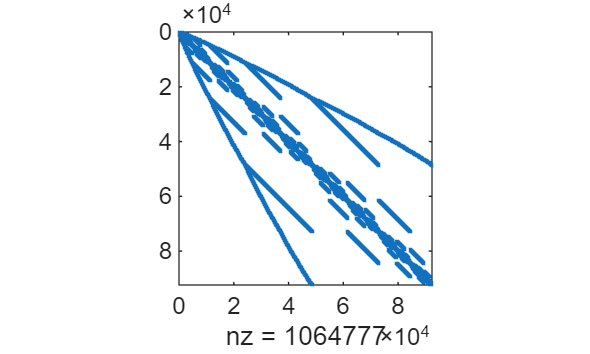

U = 10;
t = 1;

H = -t * H_kinetic + U/2 * H_interaction;
spy(H)

toc;

历时 44.197871 秒。


[Evec, Eval] = eigs(H,2,'smallestabs');
toc;
disp(num2str(diag(Eval)))



function Tag_weight = Tag_function(N_Sites, varargin)
    if nargin < 2
        Tag_weight = sqrt(100 * (1: N_Sites) + 3);
    elseif varargin{1} == "prime"
        % Use prime as tag function, very slow
        Tag_weight = sqrt(nthprime(1: N_Sites));
    end
end






function plot_circle_points(N)
    % 输入参数 N: 格点的数量

    % 生成等间距的角度
    theta = linspace(0, 2*pi, N+1); % N+1 个点，确保首尾闭合
    theta = theta(1:end-1); % 去掉最后一个重复的点

    % 计算圆上的点的坐标
    x = cos(theta);
    y = sin(theta);

    % 绘制圆
    figure;
    plot(cos(linspace(0, 2*pi, 100)), sin(linspace(0, 2*pi, 100)), 'k-'); % 画圆
    hold on;

    % 绘制格点
    plot(x, y, 'ro', 'MarkerSize', 10, 'LineWidth', 2);

    % 连接相邻的格点
    for i = 1:N
        next_i = mod(i, N) + 1; % 下一个点的索引，确保最后一个点连接到第一个点
        plot([x(i), x(next_i)], [y(i), y(next_i)], 'b-', 'LineWidth', 2);
    end

    % 设置图形属性
    axis equal;
    % title(sprintf('%d 个格点分布在圆上', N));
    % xlabel('X');
    % ylabel('Y');
    grid on;
    hold off;
end